%compare beam squint compensation between different methods
clc;
clear all;
%close all;
Ntx =[64,128,1e3,1e5];

%% system parameters
Sysparam = struct();
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3e11;%carrier frequency 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.L = 1 ; % number of paths equals to number of RF chains

## Sub-carrier frequencies

Sysparam.f = 30e9; %bandwidth 
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

%% simulation parameters
Simparam = struct();

%Simparam.phi = [0.62;0.62;0.62;0.62];
%Simparam.phi = 0.2*pi*ones(Sysparam.L,1); %AoD;
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.P = -20:5:15;% transmit power in dB
Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations

%Simparam.phi = pi*rand(Sysparam.L,1)-0.5*pi %AoD;
Simparam.phi = 0.45*pi*ones(Sysparam.L,1);%AoD;
%Simparam.phi = pi*((0.5-1/3)*rand(Sysparam.L,1)+1/3) %AoD;
SpatialDirection = sin(Simparam.phi);

set(0, 'defaultlinelinewidth', 1); set(0, 'defaultlinemarkersize', 2);
set(0, 'defaultaxesfontsize', 20); set(0, 'defaulttextfontsize', 20); 

for niter = 1:length(Ntx)
Sysparam.Nt = Ntx(niter);
for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,niter) = abs(a(:,l)'*b(:,k,l));
    end
end
clear a b
end 

fig= plot(1:Sysparam.K,arrayGain(:,:,1),1:Sysparam.K,arrayGain(:,:,2),1:Sysparam.K,arrayGain(:,:,3),1:Sysparam.K,arrayGain(:,:,4))

fig =   4×1 Line array:

  Line
  Line
  Line
  Line


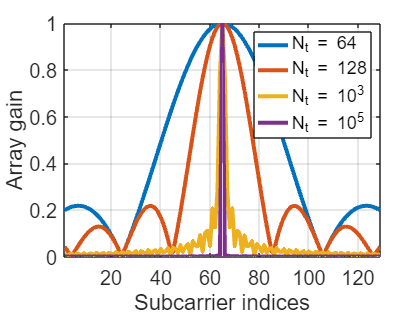

set(fig,'LineWidth',4) 
%plot(1:Sysparam.K,arrayGain(:,:,niter),'DisplayName',strcat('N_t = ',num2str(Ntx(niter))))
 grid on 
 hold on 
xlim([1,Sysparam.K])
xlabel('Subcarrier indices')
ylabel('Array gain')
legend('N_t = 64','N_t = 128','N_t = 10^3','N_t = 10^5')
 hold off

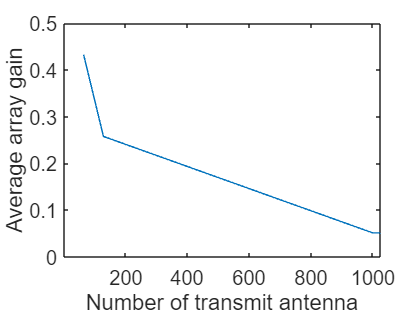

AverageGain = squeeze(sum(arrayGain,1))/Sysparam.K;
plot(Ntx,AverageGain)
xlim([2 2^10])
xlabel('Number of transmit antenna')
ylabel('Average array gain')